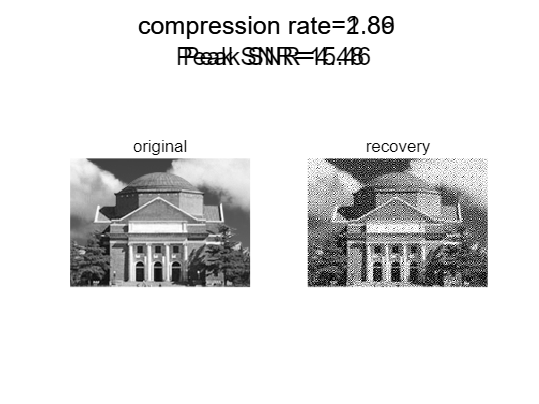

load hall.mat;
[H,W]=size(hall_gray);
%steganography
type=1;
info_len=11451;
info_content=randi([0,1],[max(info_len,H*W),1]);
info=cat(1,info_content,zeros([H*W-max(info_len,H*W),1]));
% encode and decode
[rec,cmpr,pksnr]=EnDeCoder_light(hall_gray,info,type);